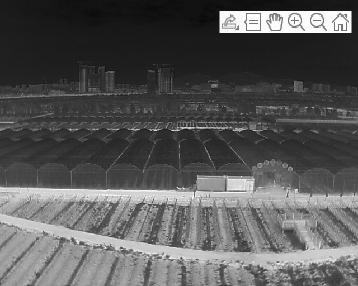

close all
clc
% 读入原始图像
img = imread('DJI_20240227162156_0001_T.JPG'); % 'your_image.jpg' 换成你的图像文件名

% 若图像为彩色，转换为RGB分量
if size(img, 3) == 3
    img_r = img(:,:,1); % 提取红色分量
    img_g = img(:,:,2); % 提取绿色分量
    img_b = img(:,:,3); % 提取蓝色分量

    % 减去颜色分量值从最大值（假设是8位图像）
    img_neg_r = 255 - img_r;
    img_neg_g = 255 - img_g;
    img_neg_b = 255 - img_b;

    % 合并颜色分量获得最终的负片效果
    img_neg = cat(3, img_neg_r, img_neg_g, img_neg_b);
else
    % 若图像为灰度图，直接计算负片
    img_neg = 255 - img;
end

% 显示原图和负片效果图像

figure,imshow(img);
title('原始图像');

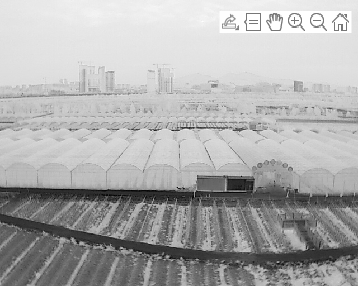


figure,imshow(img_neg);
title('负片效果图像');